dataSBM=readtable('sbmptn.xlsx')

dataSBM = 23×6 table
                     NAMAPTN                     MAT     FIS    KIM     BIO       Kelas   
    _________________________________________    ____    ___    ____    ____    __________

    {'Universitas Indonesia'                }    1083    761     843    1080    {'Tinggi'}
    {'Universitas Islam Negeri Jakarta'     }     464    342     404     666    {'Rendah'}
    {'Universitas Negeri Jakarta'           }     685    260     452     930    {'Tinggi'}
    {'Institut Pertanian Bogor'             }     592    388     560     750    {'Rendah'}
    {'Universitas Islam Negeri Gunung Djati'}     423    160     429     613    {'Tinggi'}
    {'Universitas Padjajaran'               }    1014    655    1110    1338    {'Rendah'}
    {'Universitas Pendidikan Indonesia'     } 

dataSBM

dataSBM = 23×6 table
                     NAMAPTN                     MAT     FIS    KIM     BIO       Kelas   
    _________________________________________    ____    ___    ____    ____    __________

    {'Universitas Indonesia'                }    1083    761     843    1080    {'Tinggi'}
    {'Universitas Islam Negeri Jakarta'     }     464    342     404     666    {'Rendah'}
    {'Universitas Negeri Jakarta'           }     685    260     452     930    {'Tinggi'}
    {'Institut Pertanian Bogor'             }     592    388     560     750    {'Rendah'}
    {'Universitas Islam Negeri Gunung Djati'}     423    160     429     613    {'Tinggi'}
    {'Universitas Padjajaran'               }    1014    655    1110    1338    {'Rendah'}
    {'Universitas Pendidikan Indonesia'     } 


data = dataSBM(:,2:5);
kelas = dataSBM(:,6);
[m,n] = size(kelas);
KelasTinggi = 0;
KelasRendah = 0;
kelas

kelas = 23×1 table
      Kelas   
    __________

    {'Tinggi'}
    {'Rendah'}
    {'Tinggi'}
    {'Rendah'}
    {'Tinggi'}
    {'Rendah'}
    {'Tinggi'}
    {'Tinggi'}
    {'Rendah'}
    {'Rendah'}
    {'Rendah'}
    {'Tinggi'}
    {'Tinggi'}
    {'Rendah'}
    {'Tinggi'}
    {'Tinggi'}


for i = 1:m
    if strcmp(dataSBM.Kelas{i}, 'Tinggi')
        kls(i)=1
        KelasTinggi = KelasTinggi+1;
        
    elseif strcmp(dataSBM.Kelas{i}, 'Rendah')
        kls(i)=2
        KelasRendah = KelasRendah+1;
    end
end

kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


KelasRendah

KelasRendah = 12

KelasTinggi

KelasTinggi = 11

kls

kls =      1
     2
     1
     2
     1
     2
     1
     1
     2
     2


PohonKlasifikasi = fitctree(data,kls)

PohonKlasifikasi =   ClassificationTree
           PredictorNames: {'MAT'  'FIS'  'KIM'  'BIO'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2]
           ScoreTransform: 'none'
          NumObservations: 23


  Properties, Methods


rng(1); 
ValidasiSilang = fitctree(data,kls,'CrossVal','on')

ValidasiSilang =   ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'MAT'  'FIS'  'KIM'  'BIO'}
           ResponseName: 'Y'
        NumObservations: 23
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [1 2]
         ScoreTransform: 'none'


  Properties, Methods


cabang = @(x)sum(x.IsBranch)

cabang = function_handle with value:
    @(x)sum(x.IsBranch)


mdlDefaultNumSplits = cellfun(cabang, ValidasiSilang.Trained)

mdlDefaultNumSplits =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


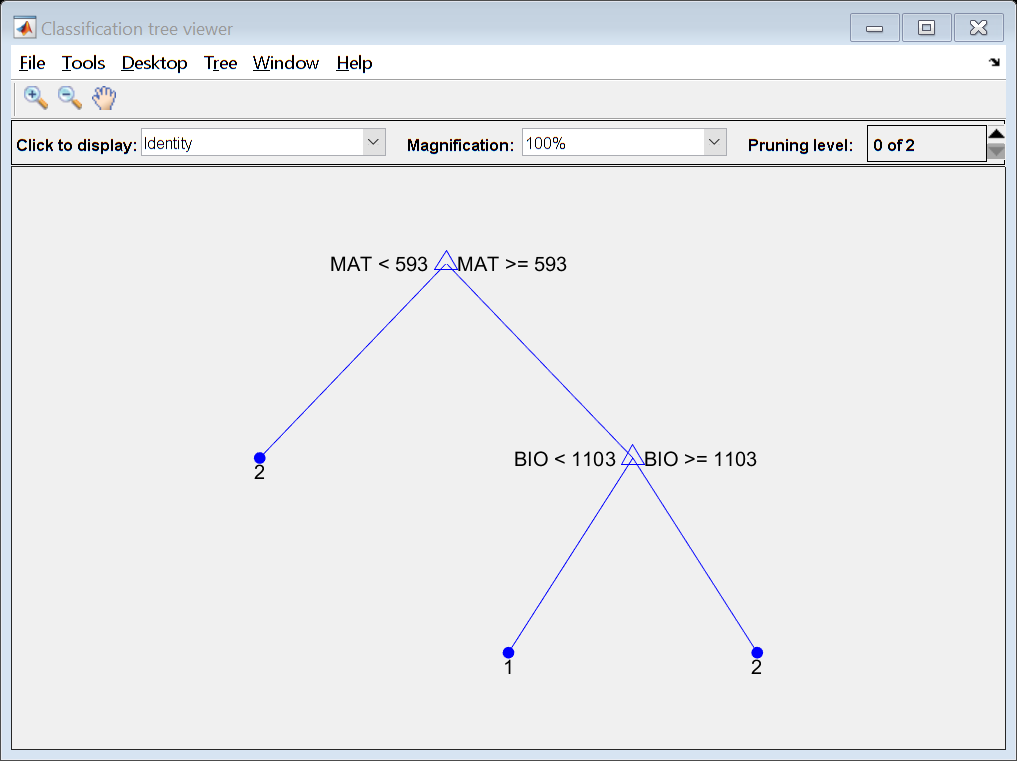

view(ValidasiSilang.Trained{1},'Mode','graph')